# Rotation by area mapping 

This is more accurate than nearest neighbor sampling. Area mapping works as follows [[ref]](http://www.leptonica.com/rotation.html) . For each dest pixel you find the 4 source pixels that it partially covers. You then compute the dest pixel value as the area-weighted average of those 4 source pixels. We make two simplifying approximations:

    The areas are computed as if the dest pixel were translated but not rotated.

    The overlap area is computed on a discrete subpixel grid. Because we are using 8 bpp images with 256 levels, it is convenient to break each pixel into a         16x16 sub-pixel grid, and count the number of overlapped sub-pixels

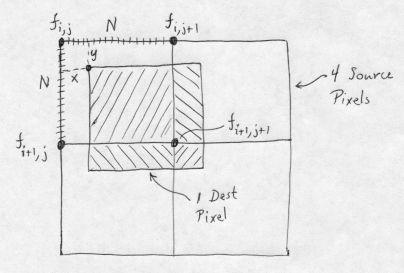


$$\text{Dest pixel value} = \frac{1}{N^2} [(N - x)(N - y)f_{i,j} + x(N - y)f_{i,j+1} + y(N - x)f_{i+1,j} + xyf_{i+1,j+1}]$$


This is the same digital filter that is obtined for *linear interpolation when arbitrarily scaling grayscale images*!

Example code [[source]](https://stackoverflow.com/a/19689081/13182960)

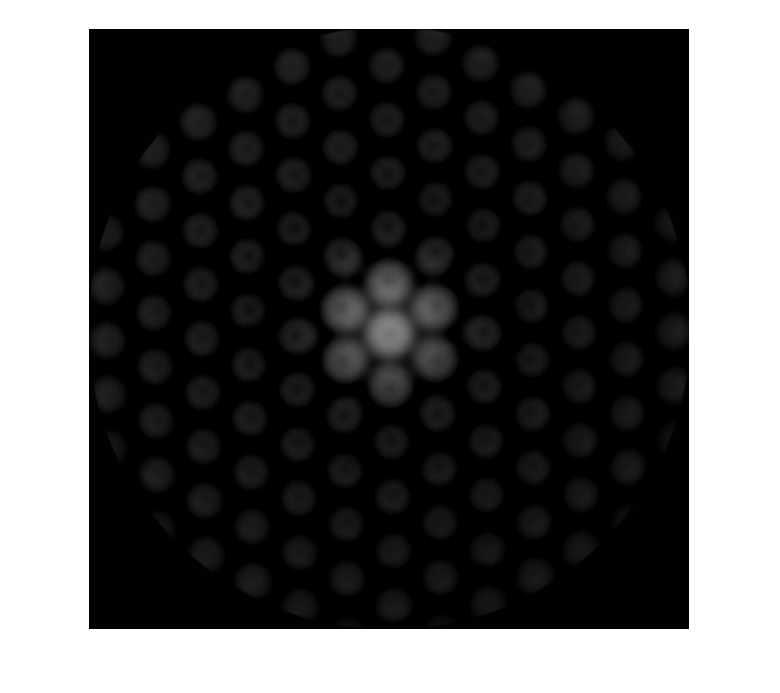

image = imread('class_19.tif');
%figure(1), clf, hold on
%subplot(1,2,1)
imshow(image);

## rotation

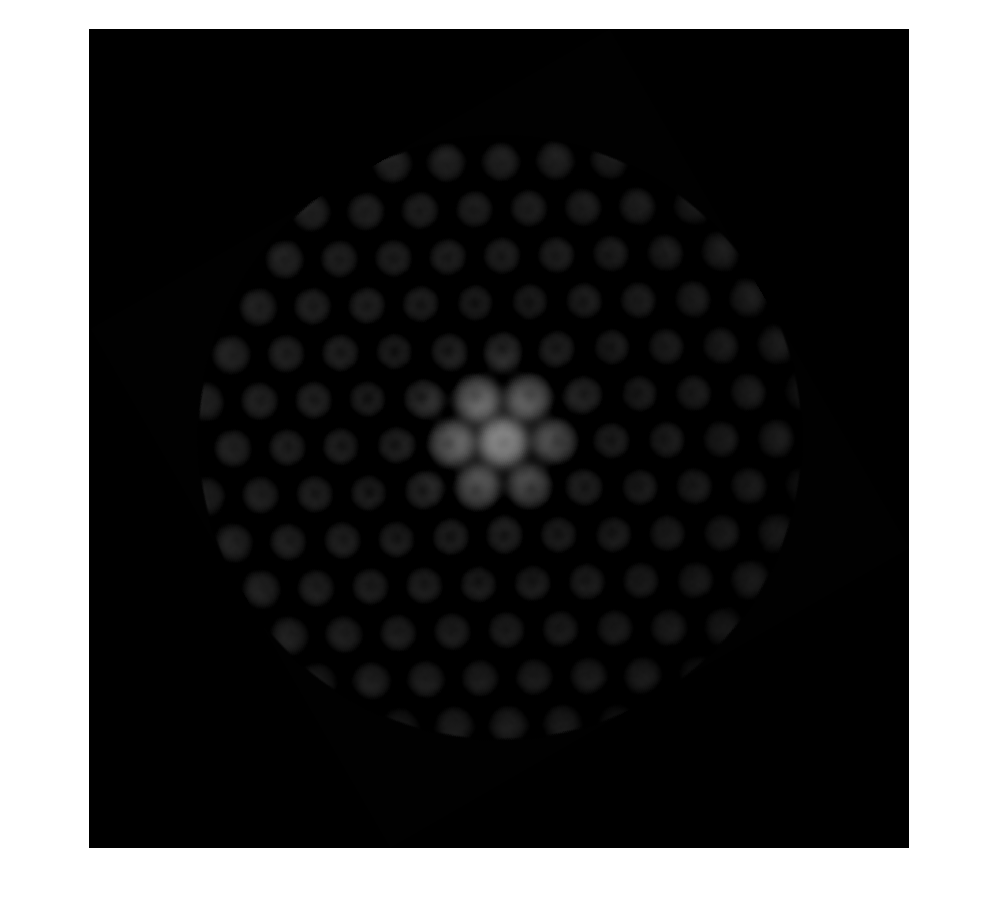


degree =30;
switch mod(degree, 360)
    % Special cases
    case 0
        imagerot = image;
    case 90
        imagerot = rot90(image);
    case 180
        imagerot = image(end:-1:1, end:-1:1);
    case 270
        imagerot = rot90(image(end:-1:1, end:-1:1));
    % General rotations
    otherwise

        % Convert to radians and create transformation matrix
        a = degree*pi/180;
        R = [+cos(a) +sin(a); -sin(a) +cos(a)];

        % Figure out the size of the transformed image
        [m,n,p] = size(image);
        dest = round( [1 1; 1 n; m 1; m n]*R ); %rotate four corners of the image
        dest = dest - min(dest) + 1;    %Since R2016a operators implicitly expand compatible arrays
        imagerot = zeros([max(dest) p],class(image));

        % Map all pixels of the transformed image to the original image
        for ii = 1:size(imagerot,1)
            for jj = 1:size(imagerot,2)
                source = ([ii jj]-dest(1,:))*R.';
                if all(source >= 1) && all(source <= [m n])

                    % Get all 4 surrounding pixels
                    C = ceil(source);
                    F = floor(source);

                    % Compute the relative areas
                    A = [...
                        ((C(2)-source(2))*(C(1)-source(1))),...
                        ((source(2)-F(2))*(source(1)-F(1)));
                        ((C(2)-source(2))*(source(1)-F(1))),...
                        ((source(2)-F(2))*(C(1)-source(1)))];

                    % Extract colors and re-scale them relative to area
                    cols = bsxfun(@times, A, double(image(F(1):C(1),F(2):C(2),:)));

                    % Assign                     
                    imagerot(ii,jj,:) = sum(sum(cols),2);

                end
            end
        end        
end

%subplot(1,2,2)
imshow(imagerot);